# Trabajo practico integrador

 

#### Evolucion de la temperatura a lo largo de la barra de acero en el tiempo

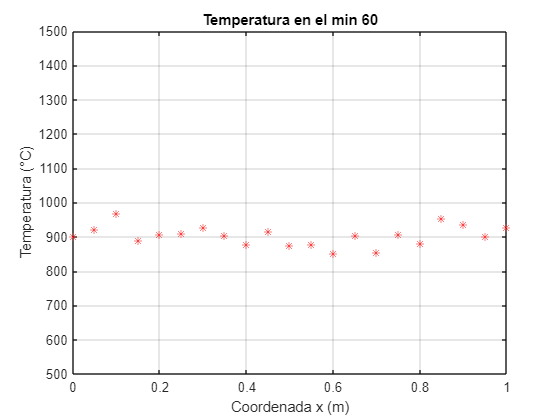

T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;

for i = 1:n
    plot(x,T(i,:),'r*')
    title(sprintf('Temperatura en el min %d',i-1))
    xlabel('Coordenada x (m)')
    ylabel('Temperatura (°C)')
    grid on
    ylim([500 1500])
    pause(0.2)
end

#### Temperatura promedio de la barra en el tiempo

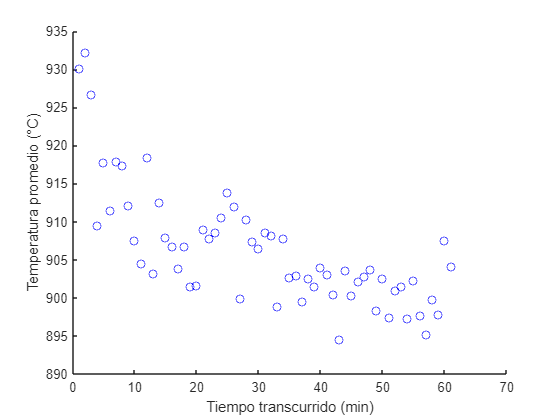

T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;
t = 0:60:3600;

[xx,tt] = meshgrid(x,t);
clf
for i = 1:n
    TemperaturaPromedio = promedio(T(i,:));
    hold on
    plot(i,TemperaturaPromedio,'bo')
    xlabel('Tiempo transcurrido (min)')
    ylabel('Temperatura promedio (°C)')
    hold off
end

#### Grafico 3D de la temperatura [°C] en funcion del tiempo [s] y el largo de la barra [m]

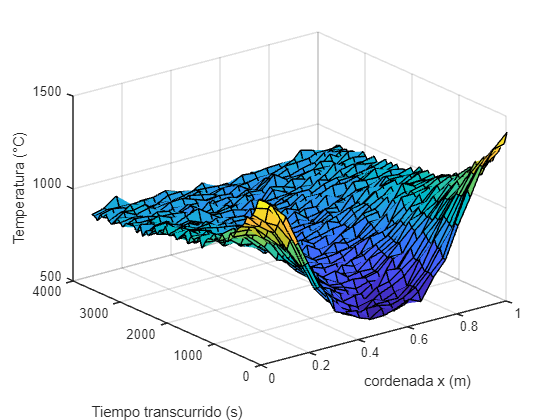

surf(xx,tt,T)
xlabel('cordenada x (m)')
ylabel('Tiempo transcurrido (s)')
zlabel('Temperatura (°C)')

## Ajuste discreto

A diferencia de un ajuste lineal, donde la funcion de ajuste es la ecuacion de una recta, o en el caso de dos variables, de un plano $\mathrm{F}\left(x,y\right)=\beta_{0\;} +\beta_1 *x_i \;+\beta_2 *\textrm{yi}\;$ , se propone la función de ajuste: $T\left(x,t\right)=c_1 +400\cos \left(c_2 x\right)e^{-\lambda 4\pi 2t} +100\cos \left(\frac{4\pi *x}{L}\right)e^{-c_3 t} \;\left\lbrack \textrm{◦C}\right\rbrack$ que predice la temperatura a lo largo de la barra para cada instante de tiempo, pero se desconocen las constantes $c_1 ,c_2 \;y\;c_3$

Se buscaran valores para $$c_1 ,c_2 \;y\;c_3$$ que minimicen el error cuadratico medio (ECM).


$$\mathrm{ECM}=\frac{\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} {\left\lbrack {\mathbf{T}}_{i,j} -\mathbf{T}\left(x_j ,t_i ,c_1 ,c_2 ,c_3 \right)\right\rbrack }^2 }{61*21}=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}$$


Los $$c_1 ,c_2 \;y\;c_3$$ que minimicen el ECM, seran los que satisfagan el siguiente sistema de ecuaciones:


$$f_1 \;=\;\frac{\partial }{\partial c_1 }\textrm{ECM}\;=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{-2*\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$



$$f_2 \;=\;\frac{\partial }{\partial c_2 }\textrm{ECM}\;=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{800x_j *\textrm{sen}\left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } *\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$



$$f_3 \;=\;\frac{\partial }{\partial c_3 }\textrm{ECM}\;=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{200t_i *\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } *\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$


Este sistema de ecuaciones no lineales se puede resolver mediante el método de Newton Raphson para sistemas de ecuaciones de la siguiente manera:


$$\left\lbrack \begin{array}{c}
c_{1,k+1} \\
c_{2,k+1} \\
c_{3,k+1} 
\end{array}\right\rbrack \approx \left\lbrack \begin{array}{c}
c_{1,k} \\
c_{2,k} \\
c_{3,k} 
\end{array}\right\rbrack -\Delta C$$



$$\;\Delta C={\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial c_1 }f_1 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_2 }f_1 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_3 }f_1 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)} \\
\frac{\partial }{\partial c_1 }f_2 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_2 }f_2 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_3 }f_2 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)} \\
\frac{\partial }{\partial c_1 }f_3 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_2 }f_3 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_3 }f_3 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)} 
\end{array}\right\rbrack }^{-1} *\left\lbrack \begin{array}{c}
f_1 \left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)\\
f_2 \left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)\\
f_3 \left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)
\end{array}\right\rbrack$$


La forma de calcular una derivada parcial numericamente es:


$$\frac{\partial }{\partial x_j }f_i \approx \frac{f_i \left(x_1 ,\ldotp \ldotp \ldotp ,x_j +\sigma x_j ,\ldotp \ldotp \ldotp ,x_n \right)-f_i \left(x_1 ,\ldotp \ldotp \ldotp ,x_j ,\ldotp \ldotp \ldotp ,x_n \right)}{\sigma x_j }$$


donde $\sigma x_j$ es un valor pequeño elegido arbitrariamente

Además es bueno tener buenas aproccimaciones iniciales, Para esto se puede probar con distintos valores de $c_1 ,c_2 \;\mathrm{y}\;c_3$ hasta que la función $T\left(x,t\right)=c_1 +400\cos \left(c_2 x\right)*e^{-\lambda 4\pi 2t} +100\cos \left(\frac{4\pi *x}{L}\right)*e^{-c_3 t} \;\left\lbrack \textrm{◦C}\right\rbrack$ aproxime los datos obtenidos empiricamente.

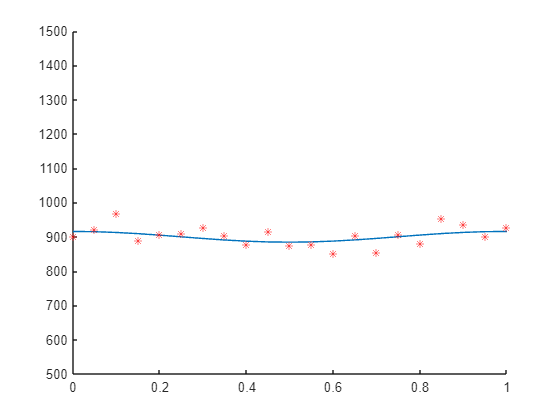

T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;
t = 0:60:3600;
L = 1;
alfa = 22.8*10^(-6);
lamda = alfa/L^2;

c1 =900;
c2 =999;
c3 = 0.16;

Temp = @(x,t) c1 + 400.*cos(c2.*x).*exp(-lamda.*4.*t.*pi.^2) + 100.*cos(4.*pi.*x./L).*exp(-c3.*t);

for i = 1:length(t)
    hold on
    plot(x,Temp(x,t(i)))
    plot(x,T(i,:),'r*')
    ylim([500 1500])
    hold off
    pause(0.2)
    if i ~= length(t)
        clf
    end    
end

J = zeros(3); % inicialización de la matriz de jacobianos
F = zeros(3,1); % inicialización del vector de funciones

dc1 = 0.01;
dc2 = 0.01;
dc3 = 0.01;
Contador = 0;

Tol = 530; 
NMax = 200;
ECM = inf; % Solo para que se ejecute el bucle while por lo menos una vez

while ECM >= Tol && Contador < NMax
    for i = 1:61
        for j = 1:21

            % Terminos generales de las sumatorias
            f1 = @(c1,c2,c3) ((-2*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281);
            f2 = @(c1,c2,c3) (800*x(j).*exp(-lamda*pi^2*4*t(i))*sin(c2*x(j))*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281;
            f3 = @(c1,c2,c3) (200*t(i)*cos(4*pi*x(j)/L)*exp(-c3*t(i))*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281;

            %%%%%%%%%%%%%%%%% Matriz de jacobianos %%%%%%%%%%%%%%%%%%%
            J(1,1) = J(1,1) + (f1(c1 + dc1,c2,c3) - f1(c1,c2,c3))/dc1;
            J(1,2) = J(1,2) + (f1(c1,c2 + dc2,c3) - f1(c1,c2,c3))/dc2;
            J(1,3) = J(1,3) + (f1(c1,c2,c3 + dc3) - f1(c1,c2,c3))/dc3;
            J(2,1) = J(2,1) + (f2(c1 + dc1,c2,c3) - f2(c1,c2,c3))/dc1;
            J(2,2) = J(2,2) + (f2(c1,c2 + dc2,c3) - f2(c1,c2,c3))/dc2;
            J(2,3) = J(2,3) + (f2(c1,c2,c3 + dc3) - f2(c1,c2,c3))/dc3;
            J(3,1) = J(3,1) + (f3(c1 + dc1,c2,c3) - f3(c1,c2,c3))/dc1;
            J(3,2) = J(3,2) + (f3(c1,c2 + dc2,c3) - f3(c1,c2,c3))/dc2;
            J(3,3) = J(3,3) + (f3(c1,c2,c3 + dc3) - f3(c1,c2,c3))/dc3;
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
            %%% Vector de funciones %%%
            F(1) = F(1) + f1(c1,c2,c3);
            F(2) = F(2) + f2(c1,c2,c3);
            F(3) = F(3) + f3(c1,c2,c3);
            %%%%%%%%%%%%%%%%%%%%%%%%%%%
        end
    end 

    %fprintf('########## Inicio de la iteracion %d ##########',Contador + 1)
    J;
    F;
    dC = J\F;
    c1k = c1;
    c2k = c2;
    c3k = c3;
    c1 = c1 - dC(1);
    c2 = c2 - dC(2);
    c3 = c3 - dC(3);
    dc1 = c1 -c1k;
    dc2 = c2 - c2k;
    dc3 = c3 -c3k;
    Contador = Contador + 1;
    
    % Cálculo del error cuadratico medio
    Temp = @(x,t) c1 + 400.*cos(c2.*x).*exp(-lamda.*4.*t.*pi.^2) + 100.*cos(4.*pi.*x./L).*exp(-c3.*t);
    ECM = 0; % inicialización del error cuadratico medio
    for i = 1:61
        for j = 1:21
            ECM =  ECM + (Temp(x(j),t(i)) - T(i,j))^2/1281;
        end
    end
    %ECM
    %fprintf('##############################################')

    VectorC1(Contador) = c1;
    VectorC2(Contador) = c2;
    VectorC3(Contador) = c3;
    VectorContador(Contador) = Contador;

    if Contador == NMax
        disp('Se llego al numero maximo de iteraciones')
    end
end

Se llego al numero maximo de iteraciones


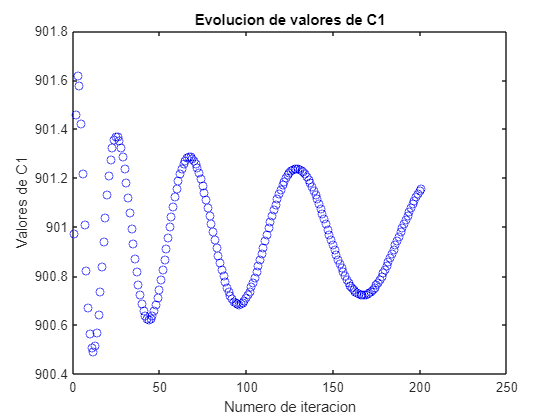

plot(VectorContador,VectorC1,'bo')
title('Evolucion de valores de C1')
ylabel('Valores de C1')
xlabel('Numero de iteracion')

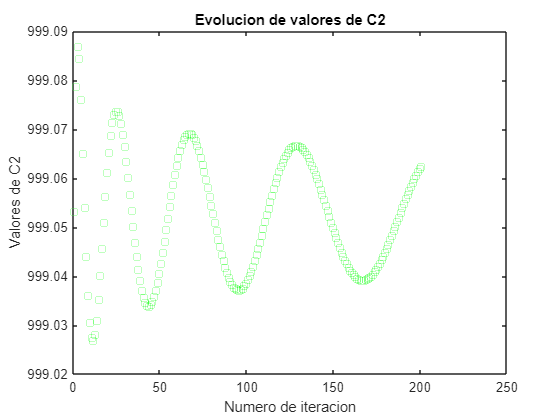


plot(VectorContador,VectorC2,'gs')
title('Evolucion de valores de C2')
ylabel('Valores de C2')
xlabel('Numero de iteracion')

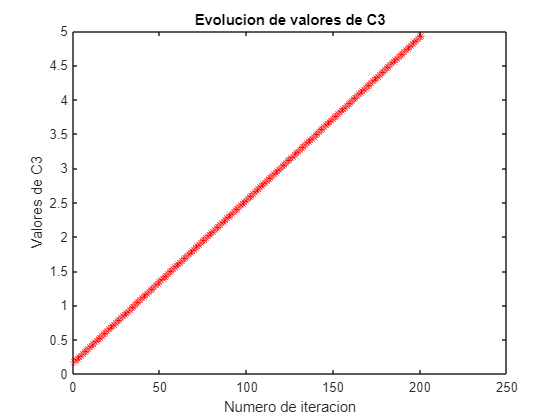


plot(VectorContador,VectorC3,'r*')
title('Evolucion de valores de C3')
ylabel('Valores de C3')
xlabel('Numero de iteracion')

#### Grafica del ajuste

Una ves obtenidas las aproccimaciones de $c_1 ,c_2 \;\mathrm{y}\;c_3$ podemos graficar $\mathrm{T}\left(x,t\right)$

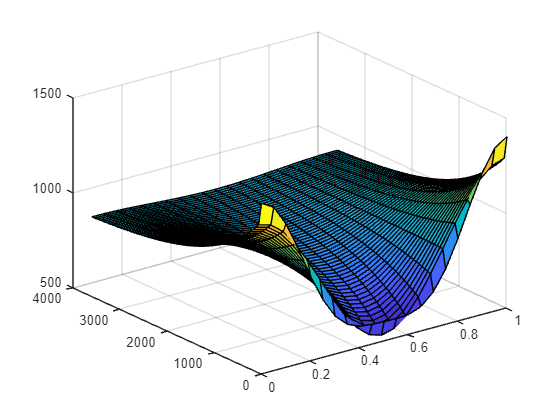

[xx,tt] = meshgrid(x,t);
surf(xx,tt,Temp(xx,tt)) ; 

Tambien podemos calcular el error cuadratico medio

fprintf('Error cuadratico medio del ajuste\nECM = %d',ECM)

Error cuadratico medio del ajuste
ECM = 5.356591e+02

## Ecuacion diferencial en derivadas parciales

#### Metodo de diferencias finitas

Fisicamente, la evolucion de la temperatura a lo largo de la barra en el tiempo, esta dada por la ecuación de conducción de calor

$\frac{\partial }{\partial t}\mathrm{T}=\lambda \frac{\partial^2 }{\partial x^2 }\mathrm{T}$            con  $\lambda =\frac{\alpha }{L^2 }$

sindo $\alpha$ el coeficiente de difusividad térmica del acero $\left(22\ldotp 8*{10}^{-6} \;\frac{m^2 }{s}\right)$ y $L$ la longitud de la barra $\left(1m\right)$.

Se tiene como condicion inicial para $t=0$ que $\mathrm{T}\left(x,0\right)=600+800*\cos^4 \left(\frac{\pi *x}{L}\right)$ y las condiciones de contorno $\frac{\partial }{\partial x}\mathrm{T}|_{x=0} =0$ y $\frac{\partial }{\partial x}\mathrm{T}|_{x=L} =0$.

Resolveremos esta ecuacion diferencial mediante el metodo de diferencias finitas, en concreto, el metodo explícito. Para esto usaremos las aproximaciones de primer orden; centrada para la derivada espacial y adelantada para la derivada temporal


$$\frac{\partial^2 }{\partial x^2 }\mathrm{T}=\frac{{\mathrm{T}}_{i,j+1} -2{\mathrm{T}}_{i,j} +{\mathrm{T}}_{i,j-1} }{\Delta x^2 }$$



$$\frac{\partial }{\partial t}\mathrm{T}=\frac{{\mathrm{T}}_{i+1,j} -{\mathrm{T}}_{i,j} }{\Delta t}$$


donde el indice $i$ representa un instante de tiempo y $j$ una pequeña parte de la barra.

Remplazando estas aproximaciones en la ecuacion diferencial se tiene:


$$\frac{{\mathrm{T}}_{i+1,j} -{\mathrm{T}}_{i,j} }{\Delta t}=\lambda *\frac{{\mathrm{T}}_{i,j+1} -2{\mathrm{T}}_{i,j} +{\mathrm{T}}_{i,j-1} }{\Delta x^2 }$$


Despejando la temperatura en el proximo instante de tiempo ${\mathrm{T}}_{i+1,j}$, se llega a la exprecion:


$${\mathrm{T}}_{i+1,j} ={\mathrm{T}}_{i,j} +\frac{\lambda *\Delta t}{\Delta x^2 }*\left({\mathrm{T}}_{i,j+1} -2{\mathrm{T}}_{i,j} +{\mathrm{T}}_{i,j-1} \right)$$


Notar que con esta expresion no se puede calcular la temperatura en los extremos de la barra para cada instante de tiempo. Cuando estás en el primer $j$, no hay un ${\mathrm{T}}_{i,j-1}$, de la misma forma que cuando estás en el ultimo $j$,  no hay un ${\mathrm{T}}_{i,j+1}$.

La temperatura en los extremos la podemos inferir a partir de las condiciones de borde $\frac{\partial }{\partial x}\mathrm{T}|_{x=0} =0$ y $\frac{\partial }{\partial x}\mathrm{T}|_{x=L} =0$. Estas condiciones lo que dicen es que no hay transferencia de calor entre los extremos de la barra y la parte de la barra adyacente a los mismos, por lo que deben estar necesariamente a la misma temperatura.

si $j=1,2,3,4,\ldotp \ldotp \ldotp ,n$ entoncen ${\mathrm{T}}_{i,1} ={\mathrm{T}}_{i,2}$ y ${\mathrm{T}}_{i,n} ={\mathrm{T}}_{i,n-1}$

#### Convergecia y estabilidad

Convergencia significa que conforme $\Delta x$ y $\Delta t$ tienden a cero, los resultados del metodo de diferencias finitas se aproximarán a la solucion verdadera. Estabilidad significa que los errores en cualquier estapa del calculo no se amplifican, sino que se atenúan comforme avanza el cálculo.

Existen diferentes métodos para determinar el crecimiento en el tiempo del error en el proceso de cálculo de la solución. Si el error no crece con el tiempo, el método es estable.

Segun el criterio de Von Newman el metodo explícito es convergente y estable si


$$\Delta t\le \frac{1}{2}*\frac{{\Delta x}^2 }{\lambda }$$


para un $\Delta x=0,05\;m$ se tiene


$$\Delta t\le \frac{1}{2}*0,\frac{{\left(0,05\;\right)}^2 }{22,8*{10}^{-6} }=54,8245614$$


Elijo $\Delta t=30\;s$, ya que cumple con el criterio

T = importdata('TempMed.mat');
alfa = 22.8*10^(-6);
L = 1;
lamda = alfa/L^2;

dx = 0.05; % Elegido arbitrariamente
dt = 30; % Tiene que satisfacer el criterio de Von Newman
x = 0:dx:1;
t = 0:dt:3600;

TempInicial = @(x) 600 + 800*(cos(pi*x/L).^4);

Tsol = zeros(length(t),length(x));
Tsol(1,:) = TempInicial(x);
for i = 1:length(t) - 1 % Filas
    for j = 2:length(x) - 1 % Columnas
        Tsol(i + 1,j) = Tsol(i,j) + (lamda*dt)/(dx^2)*(Tsol(i,j+1) - 2*Tsol(i,j) + Tsol(i,j-1));
    end
    % Condiciones de borde
    Tsol(i + 1,1) = Tsol(i+1,2);
    Tsol(i + 1,end) = Tsol(i+1,end-1);
end

#### Grafica de la solucion

Una vez calculado numericamente la solucion de la ecuacion diferencial, podemos graficarla

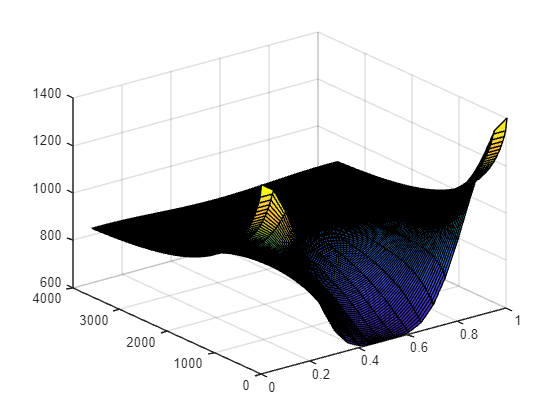

[xx,tt] = meshgrid(x,t);
surf(xx,tt,Tsol)

Tambien podemos calcular el error cuadratico medio

ECM = 0; % inicialización del error cuadratico medio
if dt == 30
    for i = 1:61
        for j = 1:21
            ECM =  ECM + (Tsol(2*i-1,j) - T(i,j))^2/1281;
        end
    end
elseif dt == 20
    for i = 1:61
        for j = 1:21
            ECM =  ECM + (Tsol(3*i-2,j) - T(i,j))^2/1281;
        end
    end
elseif dt == 10
    for i = 1:61
        for j = 1:21
            ECM =  ECM + (Tsol(6*i-5,j) - T(i,j))^2/1281;
        end
    end
else 
    disp('dt no es valido')
end
fprintf('Error cuadratico medio de la solucion a la ecuacion de conducción de calor\nECM = %d',ECM)

Error cuadratico medio de la solucion a la ecuacion de conducción de calor
ECM = 1.030581e+03